clear; 
clc;

 nostim_trials = 1:12;
 stim_trials = 13:24;

% data_1618 = load('1618_early_stim_data.mat');
% data_1681 = load('1681_early_stim_data.mat');
% data_1722 = load('1722_early_stim_data.mat');
% data_test = load('2392_early_stim_data.mat');
% 
% data_1618 = load('1618_late_stim_data.mat');
% data_1681 = load('1681_late_stim_data.mat');
% data_1722 = load('1722_late_stim_data.mat');

% data_2209 = load('2209_late_stim_data.mat');
% data_2210 = load('2210_late_stim_data.mat');
% data_2213 = load('2213_late_stim_data.mat');
% data_2223 = load('2223_late_stim_data.mat');
% 
% data_2209 = load('2209_early_stim_data.mat');
% data_2210 = load('2210_early_stim_data.mat');
% data_2213 = load('2213_early_stim_data.mat');
% data_2223 = load('2223_early_stim_data.mat');

% 
% data_2346 = load('2346_early_stim_data.mat');
data_2350 = load('2350_early_stim_data.mat');
% data_2351 = load('2351_early_stim_data.mat');
data_2359 = load('2359_early_stim_data.mat');
% data_2366 = load('2366_early_stim_data.mat');
data_2379 = load('2379_early_stim_data.mat');
% 
% 
% [S_aligned, N_aligned, C_aligned, Q_aligned] = unpack_combine(data_2209.big_mat, ...
%                                                                           data_2210.big_mat, ...
%                                                                           data_2213.big_mat, ...
%                                                                           data_2223.big_mat,...
%                                                                           data_1722.big_mat);
[S_aligned, N_aligned, C_aligned, Q_aligned] = unpack_combine(data_2350.big_mat, ...
                                                                          data_2359.big_mat,...
                                                                          data_2379.big_mat);
% % 
% [S_aligned, N_aligned, C_aligned, Q_aligned] = unpack_combine(data_test.big_mat);
% 
% [S_aligned, N_aligned, C_aligned, Q_aligned] = unpack_combine(data_2209.big_mat, ...
%                                                                           data_2210.big_mat, ...
%                                                                           data_2213.big_mat);

% [S_aligned, N_aligned, C_aligned, Q_aligned] = unpack_combine(data_1618.big_mat, ...
%                                                                           data_1722.big_mat);

% data_1683 = load('1683_early_stim_data.mat');
% data_1723 = load('1723_early_stim_data.mat');
% 
% [S_aligned_df, N_aligned_df, C_aligned_df, Q_aligned_df] = unpack_combine(data_1683.big_mat, ...
%                                                                           data_1723.big_mat);
% 
% 

% Tranform aligned traces as change from baseline. Baseline is from -3 to 0 (frame 21 to 50)
% This excludes the stimulation period
BL = 21:50; %21:50 previously
S_aligned_df = S_aligned - mean(S_aligned(:, :, BL), 3);
N_aligned_df = N_aligned - mean(N_aligned(:, :, BL), 3);
C_aligned_df = C_aligned - mean(C_aligned(:, :, BL), 3);
Q_aligned_df = Q_aligned - mean(Q_aligned(:, :, BL), 3);

% Take 0-5s of the response (52:101). Convert data to 10 time bins of 500 ms
S_aligned_binned = bin_data(S_aligned_df(:,:, 52:101), 10);
N_aligned_binned = bin_data(N_aligned_df(:,:, 52:101), 10);
C_aligned_binned = bin_data(C_aligned_df(:,:, 52:101), 10);
Q_aligned_binned = bin_data(Q_aligned_df(:,:, 52:101), 10);

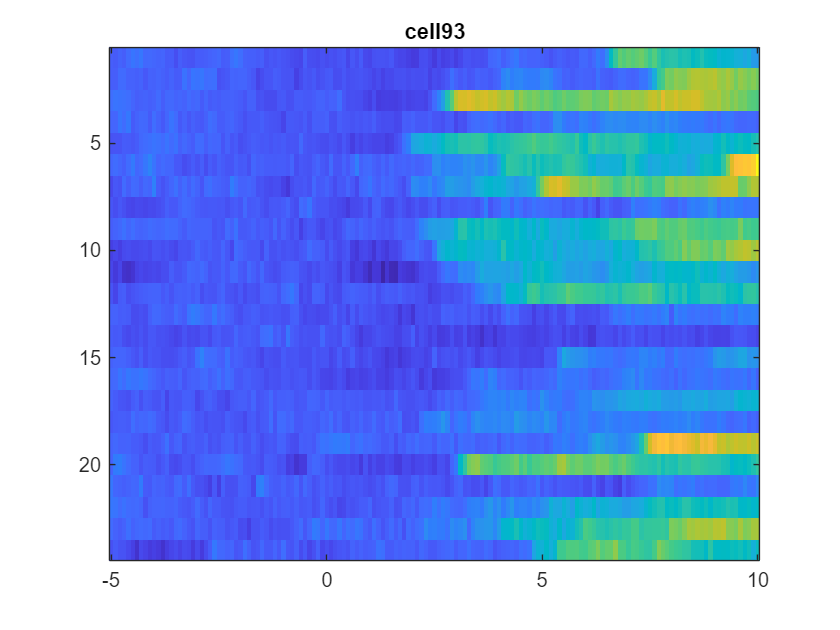

%Animate PETH for each cell
heatmap_slide_show(S_aligned_df, 5, 10, sig_S);

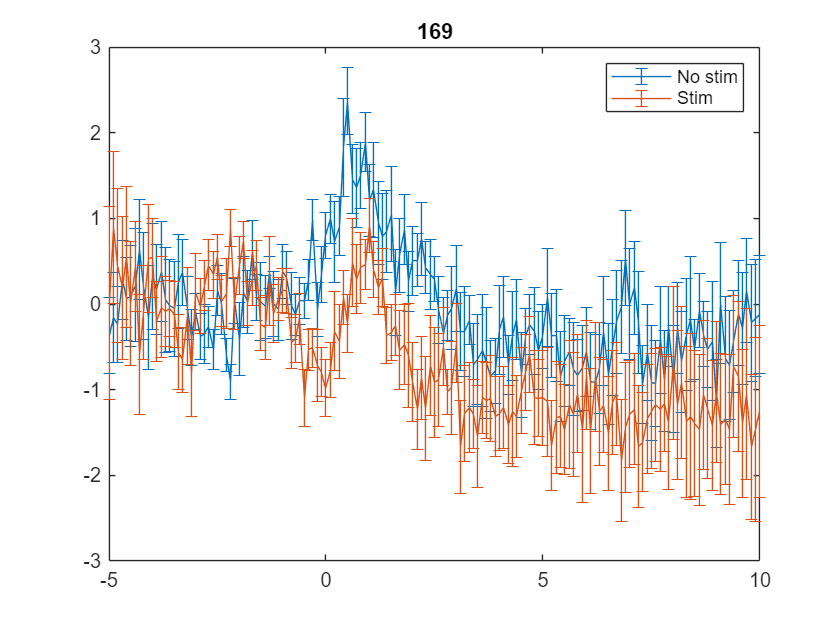

% Animate mean traces for each cell
mean_trace_slide_show(S_aligned_df, 5, 10, stim_trials, nostim_trials, sig_S);

% Get mean traces of representativce neurons (1 taste).
cell_trace_tab = sample_trace_1T(C_aligned_df, 361);
filename = "Early stim cell 361 C.xlsx";
writetable(cell_trace_tab, filename, "sheet", "Mean traces")

% Find the number of neurons responsive to each taste
% Use p-value of 0.005 (Bonferroni correction)
threshold = 1;
alpha = 0.001;

% Sweet
S_nostim_responsive = test_responsive(S_aligned_binned(:, nostim_trials, :), alpha, threshold);
S_stim_responsive = test_responsive(S_aligned_binned(:, stim_trials, :), alpha, threshold);
sum(S_nostim_responsive)

ans = 160

sum(S_stim_responsive)

ans = 204


% Salty
N_nostim_responsive = test_responsive(N_aligned_binned(:, nostim_trials, :), alpha, threshold);
N_stim_responsive = test_responsive(N_aligned_binned(:, stim_trials, :), alpha, threshold);
sum(N_nostim_responsive)

ans = 136

sum(N_stim_responsive)

ans = 133


% Sour
C_nostim_responsive = test_responsive(C_aligned_binned(:, nostim_trials, :), alpha, threshold);
C_stim_responsive = test_responsive(C_aligned_binned(:, stim_trials, :), alpha, threshold);
sum(C_nostim_responsive)

ans = 233

sum(C_stim_responsive)

ans = 201


% Bitter
Q_nostim_responsive = test_responsive(Q_aligned_binned(:, nostim_trials, :), alpha, threshold);
Q_stim_responsive = test_responsive(Q_aligned_binned(:, stim_trials, :), alpha, threshold);
sum(Q_nostim_responsive)

ans = 113

sum(Q_stim_responsive)

ans = 96


taste_responsive = find(S_nostim_responsive|S_stim_responsive| ...
                        N_nostim_responsive|N_stim_responsive| ...
                        C_nostim_responsive|C_stim_responsive| ...
                        Q_nostim_responsive|Q_stim_responsive);

% Find the number of taste-discrimantive neurons
% No-stim trials
[main_nostim, interact_nostim, significant_nostim] = test_discriminative(S_aligned_binned(:, nostim_trials, :), ...
    N_aligned_binned(:, nostim_trials, :), ...
    C_aligned_binned(:, nostim_trials, :), ...
    Q_aligned_binned(:, nostim_trials, :));

significant_nostim

significant_nostim =      2     3     8     9    11    15    17    18    24    26    27    29    30    32    34    35    36    37    40    44    45    49    53    54    55    57    58    61    64    69    76    77    82    83    87    91    92    93    96    98    99   100   101   106   107   109   116   118   119   122



% Stim trials
[main_stim, interact_stim, significant_stim] = test_discriminative(S_aligned_binned(:, stim_trials, :), ...
    N_aligned_binned(:, stim_trials, :), ...
    C_aligned_binned(:, stim_trials, :), ...
    Q_aligned_binned(:, stim_trials, :));

significant_stim

significant_stim =      3     8    10    11    15    17    18    23    25    26    27    30    32    34    35    36    37    40    42    44    45    49    57    58    59    65    69    77    80    82    87    91    96    97    98   100   101   106   108   109   110   114   116   118   119   120   122   128   130   131



discriminative_neurons = union(significant_nostim,significant_stim);

% Identify cell-taste pairs that are significantly modulated by stimulation
[main_S, interact_S, sig_S] = test_modulated(S_aligned_binned, 12);
[main_N, interact_N, sig_N] = test_modulated(N_aligned_binned, 12);
[main_C, interact_C, sig_C] = test_modulated(C_aligned_binned, 12);
[main_Q, interact_Q, sig_Q] = test_modulated(Q_aligned_binned, 12);

sig_mod = union(union(sig_S, sig_C), union(sig_Q, sig_N))

sig_mod =      1     2     7    12    15    21    25    29    34    35    42    46    47    48    65    66    87    88    89    90    93    98   101   102   108   109   111   116   120   122   123   125   131   133   135   136   138   142   146   152   159   164   165   167   169   172   173   174   178   181


sig_mod_D = intersect(sig_mod, discriminative_neurons)

sig_mod_D =      2    15    25    29    34    35    42    65    87    93    98   101   108   109   116   120   122   125   131   133   138   142   146   152   159   165   167   169   172   173   178   181   187   188   191   193   197   199   200   202   208   209   210   212   213   215   226   228   231   238


sig_mod_R = intersect(sig_mod, taste_responsive)'

sig_mod_R =      2    15    25    29    34    35    42    46    47    66    87    88    89    90    93    98   101   102   109   111   116   122   123   125   131   133   136   138   142   146   152   159   164   165   167   172   173   174   178   181   187   188   191   192   193   194   197   199   200   201


sig_mod_DR = intersect(sig_mod_D, taste_responsive)'

sig_mod_DR =      2    15    25    29    34    35    42    87    93    98   101   109   116   122   125   131   133   138   142   146   152   159   165   167   172   173   178   181   187   188   191   193   197   199   200   202   208   209   210   212   213   215   226   228   231   238   243   245   246   253


D_and_R = intersect(discriminative_neurons, taste_responsive)'

D_and_R =      2     9    10    11    15    17    23    24    25    26    27    29    30    34    35    36    37    40    42    44    45    49    55    57    58    59    61    69    76    77    80    87    91    93    96    98    99   100   101   106   109   114   116   118   119   122   125   128   130   131


sig_S = intersect(sig_S, sig_mod_R);
sig_N = intersect(sig_N, sig_mod_R);
sig_C = intersect(sig_C, sig_mod_R);
sig_Q = intersect(sig_Q, sig_mod_R);

% Define which cell list to use for analysis
cell_list_for_analysis = sig_mod_DR;

% Creat a matrix that represent significantly modulated cell-taste
% pairs as 1 and others as 0.

cell_list = 1:size(S_aligned,1);
sig_S_bool = ismember(cell_list, sig_S);
sig_N_bool = ismember(cell_list, sig_N);
sig_C_bool = ismember(cell_list, sig_C);
sig_Q_bool = ismember(cell_list, sig_Q);

sig_bool = [sig_S_bool; sig_N_bool; sig_C_bool; sig_Q_bool];
sig_bool_DR = sig_bool(:, sig_mod_DR);
clf 
%imagesc(sig_bool_DR)
histcounts(sum(sig_bool_DR, 1))

ans =     73    13     6     1


sum(sig_bool_DR, 2)

ans =     48
    22
    25
    26



sum(sig_bool_DR, "all")

ans = 121

numel(sig_bool_DR)

ans = 372

clf
imagesc(mod_direction)

Unrecognized function or variable 'mod_direction'.

imagesc(mod_direction_abs)

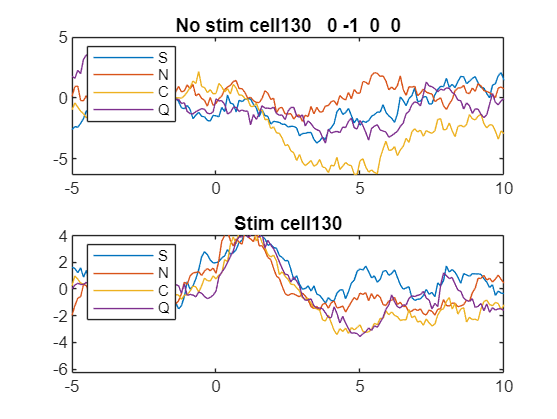

% Visualize mean taste response in nostim and stim trials
clf
comparison = compare_taste_response(S_aligned_df, N_aligned_df, C_aligned_df, Q_aligned_df, 5, 10, mod_direction, 130);

% Get mean trace of representativce neurons (4 tastes).
[nostim_trace_tab, stim_trace_tab] = sample_trace_4T(S_aligned_df, ...
    N_aligned_df, ...
    C_aligned_df, ...
    Q_aligned_df, 235);
filename = "Early stim cell 235 4T.xlsx";
writetable(nostim_trace_tab, filename, "sheet", "No stim")
writetable(stim_trace_tab, filename, "sheet", "Stim")

S_binned_sig_nostim = S_aligned_binned(cell_list_for_analysis, nostim_trials, :);
N_binned_sig_nostim = N_aligned_binned(cell_list_for_analysis, nostim_trials, :);
C_binned_sig_nostim = C_aligned_binned(cell_list_for_analysis, nostim_trials, :);
Q_binned_sig_nostim = Q_aligned_binned(cell_list_for_analysis, nostim_trials, :);

combined_binned_sig_nostim = cat(2,S_binned_sig_nostim, N_binned_sig_nostim, C_binned_sig_nostim, Q_binned_sig_nostim);

S_binned_sig_stim = S_aligned_binned(cell_list_for_analysis, stim_trials, :);
N_binned_sig_stim = N_aligned_binned(cell_list_for_analysis, stim_trials, :);
C_binned_sig_stim = C_aligned_binned(cell_list_for_analysis, stim_trials, :);
Q_binned_sig_stim = Q_aligned_binned(cell_list_for_analysis, stim_trials, :);

combined_binned_sig_stim = cat(2,S_binned_sig_stim, N_binned_sig_stim, C_binned_sig_stim, Q_binned_sig_stim);


% Bootstrapped population decoding accross time bins
no_stim_decode_accuracy_boot = decode_bin_boot(combined_binned_sig_nostim, 10, 100, 50);

bootstrap 1
bootstrap 2
bootstrap 3
bootstrap 4
bootstrap 5
bootstrap 6
bootstrap 7
bootstrap 8
bootstrap 9
bootstrap 10
bootstrap 11
bootstrap 12
bootstrap 13
bootstrap 14
bootstrap 15
bootstrap 16
bootstrap 17
bootstrap 18
bootstrap 19
bootstrap 20
bootstrap 21
bootstrap 22
bootstrap 23
bootstrap 24
bootstrap 25
bootstrap 26
bootstrap 27
bootstrap 28
bootstrap 29
bootstrap 30
bootstrap 31
bootstrap 32
bootstrap 33
bootstrap 34
bootstrap 35
bootstrap 36
bootstrap 37
bootstrap 38
bootstrap 39
bootstrap 40
bootstrap 41
bootstrap 42
bootstrap 43
bootstrap 44
bootstrap 45
bootstrap 46
bootstrap 47
bootstrap 48
bootstrap 49
bootstrap 50


stim_decode_accuracy_boot = decode_bin_boot(combined_binned_sig_stim, 10, 100, 50);

bootstrap 1
bootstrap 2
bootstrap 3
bootstrap 4
bootstrap 5
bootstrap 6
bootstrap 7
bootstrap 8
bootstrap 9
bootstrap 10
bootstrap 11
bootstrap 12
bootstrap 13
bootstrap 14
bootstrap 15
bootstrap 16
bootstrap 17
bootstrap 18
bootstrap 19
bootstrap 20
bootstrap 21
bootstrap 22
bootstrap 23
bootstrap 24
bootstrap 25
bootstrap 26
bootstrap 27
bootstrap 28
bootstrap 29
bootstrap 30
bootstrap 31
bootstrap 32
bootstrap 33
bootstrap 34
bootstrap 35
bootstrap 36
bootstrap 37
bootstrap 38
bootstrap 39
bootstrap 40
bootstrap 41
bootstrap 42
bootstrap 43
bootstrap 44
bootstrap 45
bootstrap 46
bootstrap 47
bootstrap 48
bootstrap 49
bootstrap 50


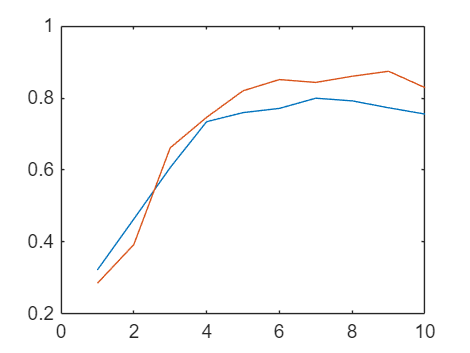

%mean(no_stim_decode_accuracy_boot, 2)
%mean(stim_decode_accuracy_boot, 2)

clf
plot(1:10, mean(no_stim_decode_accuracy_boot, 2))
hold on
plot(1:10, mean(stim_decode_accuracy_boot, 2))
hold off


% no_stim_decode_accuracy_tab = array2table(no_stim_decode_accuracy);
% stim_decode_accuracy_tab = array2table(stim_decode_accuracy);
% 
%  filename = "1958 early retest decoding accuracy (10-fold CV responsive).xlsx";
%   writetable(no_stim_decode_accuracy_tab, filename, "Sheet", "No stim");
%   writetable(stim_decode_accuracy_tab, filename, "Sheet", "Stim");

% population decoding using all bins of each neuron
pop_sizes = [5, 10, 15, 20, 25, 30, 35, 40, 45, 50];
%pop_sizes = [10, 20, 30, 40, 50, 60, 70, 80, 90, 100];
%pop_sizes = [20, 40, 60, 80, 100];
pop_decode_accuracy_nostim = decode_pop_sizes(combined_binned_sig_nostim, 6, pop_sizes, 50);
pop_decode_accuracy_stim = decode_pop_sizes(combined_binned_sig_stim, 6, pop_sizes, 50);

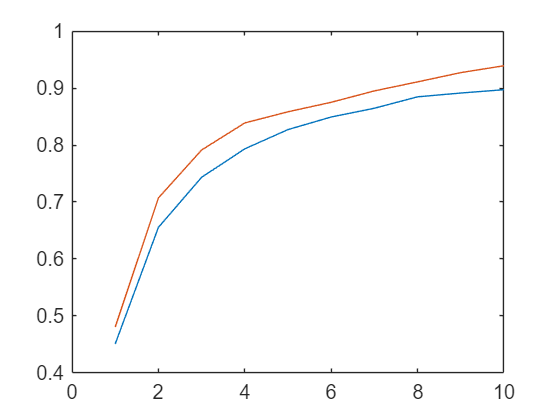


mean_pop_accuracy_nostim = mean(pop_decode_accuracy_nostim, 2);
mean_pop_accuracy_stim = mean(pop_decode_accuracy_stim, 2);
clf
plot(1:10, mean_pop_accuracy_nostim)
hold on
plot(1:10, mean_pop_accuracy_stim)
hold off


pop_acc_diff = mean_pop_accuracy_stim - mean_pop_accuracy_nostim;

% no_stim_decode_pop_tab = array2table(pop_decode_accuracy_nostim);
% stim_decode_pop_tab = array2table(pop_decode_accuracy_stim); 
% filename = "Cohort 3 population size decoding accuracy (1+3 exclude subjects).xlsx";
%   writetable(no_stim_decode_pop_tab, filename, "Sheet", "No stim");
%   writetable(stim_decode_pop_tab, filename, "Sheet", "Stim");

% permutation test for population decoding accuracy. This block may take
% more than 10 hrs to complete due to the number of permutations performed
tic
n_perms = 1000;
n_boots = 50;
diff_acc_distribution = zeros(length(pop_sizes), n_perms);

for perm = 1:n_perms
    rng(perm, "twister");
    [nostim_perm, stim_perm] = permute_datasets(combined_binned_sig_nostim, combined_binned_sig_stim);
    pop_decode_accuracy_nostim = decode_pop_sizes(nostim_perm, 6, pop_sizes, n_boots);
    pop_decode_accuracy_stim = decode_pop_sizes(stim_perm, 6, pop_sizes, n_boots);

    mean_pop_accuracy_nostim = mean(pop_decode_accuracy_nostim, 2);
    mean_pop_accuracy_stim = mean(pop_decode_accuracy_stim, 2);
    diff_acc_distribution(:, perm) = mean_pop_accuracy_stim - mean_pop_accuracy_nostim;
end
toc

Elapsed time is 44029.711345 seconds.


pop_pvalues = zeros(length(pop_sizes), 1);
for i = 1:length(pop_sizes)
    null_dist = diff_acc_distribution(i, :);
    acc_diff = pop_acc_diff(i);
    p_val = mean(abs(null_dist) >= abs(acc_diff));
    pop_pvalues(i) = p_val;
end


% Combine trial average data for palatability analysis
S_binned_trial_means_nostim = squeeze(mean(S_binned_sig_nostim, 2)); 
N_binned_trial_means_nostim = squeeze(mean(N_binned_sig_nostim, 2));
C_binned_trial_means_nostim = squeeze(mean(C_binned_sig_nostim, 2));
Q_binned_trial_means_nostim = squeeze(mean(Q_binned_sig_nostim, 2));

combined_trial_means_nostim = cat(3, S_binned_trial_means_nostim,...
                                N_binned_trial_means_nostim,...
                                C_binned_trial_means_nostim,...
                                Q_binned_trial_means_nostim);

S_binned_trial_means_stim = squeeze(mean(S_binned_sig_stim, 2)); 
N_binned_trial_means_stim = squeeze(mean(N_binned_sig_stim, 2));
C_binned_trial_means_stim = squeeze(mean(C_binned_sig_stim, 2));
Q_binned_trial_means_stim = squeeze(mean(Q_binned_sig_stim, 2));

combined_trial_means_stim = cat(3, S_binned_trial_means_stim,...
                                N_binned_trial_means_stim,...
                                C_binned_trial_means_stim,...
                                Q_binned_trial_means_stim);

% This replaces a no-stim mean trace with stim one, only when the
% cell-taste pair is significantly modulated.
combined_trial_means_stim_swap = combined_trial_means_nostim;
for cell = 1:size(combined_trial_means_stim, 1)
    for taste = 1:4
        if sig_bool_DR(taste, cell) == 1
            combined_trial_means_stim_swap(cell, :, taste) = combined_trial_means_stim(cell, :, taste);
        end
    end
end

combined_trial_means_SN_swap = combined_trial_means_nostim;
for cell = 1:size(combined_trial_means_stim, 1)
    for taste = [1,4]
        if sig_bool_DR(taste, cell) == 1
            combined_trial_means_SN_swap(cell, :, taste) = combined_trial_means_stim(cell, :, taste);
        end
    end
end

combined_trial_means_CQ_swap = combined_trial_means_nostim;
for cell = 1:size(combined_trial_means_stim, 1)
    for taste = [2,3]
        if sig_bool_DR(taste, cell) == 1
            combined_trial_means_CQ_swap(cell, :, taste) = combined_trial_means_stim(cell, :, taste);
        end
    end
end

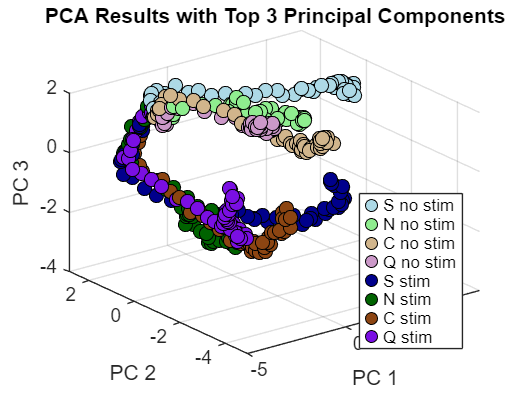

% trial_mean_design_mat = cat(2, S_binned_trial_means_nostim, ...
%                                 N_binned_trial_means_nostim, ...
%                                 C_binned_trial_means_nostim, ...
%                                 Q_binned_trial_means_nostim, ...
%                                 S_binned_trial_means_stim, ...
%                                 N_binned_trial_means_stim, ...
%                                 C_binned_trial_means_stim, ...
%                                 Q_binned_trial_means_stim)';
% trial_mean_design_mat_norm = trial_mean_design_mat ./ max_val(cell_list_for_analysis)';


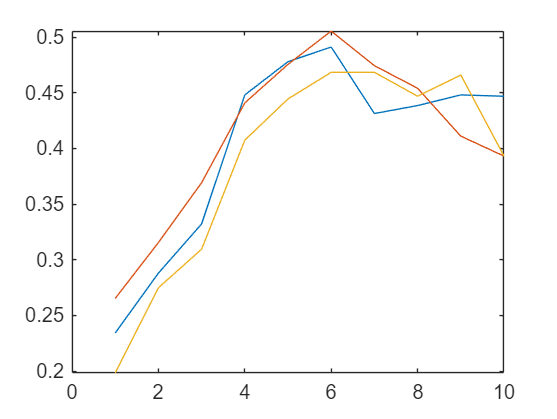

% Calculate platability correlation (sigmod taste responsive cells)
nostim_palatability_corr = palatability_corr(combined_trial_means_nostim);
stim_palatability_corr = palatability_corr(combined_trial_means_stim);
stim_swap_palatability_corr = palatability_corr(combined_trial_means_stim_swap);
clf
plot(1:10, mean(nostim_palatability_corr, 2))
hold on
plot(1:10, mean(stim_palatability_corr, 2))
plot(1:10, mean(stim_swap_palatability_corr, 2))
hold off


nostim_palatability_tab = array2table(nostim_palatability_corr);
stim_palatability_tab = array2table(stim_palatability_corr);
stim_swap_palatability_tab = array2table(stim_swap_palatability_corr);

% filename = "Cohort 1+3 early palatability corr (Kendall).xlsx";
% writetable(nostim_palatability_tab, filename, "Sheet", "No stim");
% writetable(stim_palatability_tab, filename, "Sheet", "Stim");
% writetable(stim_swap_palatability_tab, filename, "Sheet", "Swap");

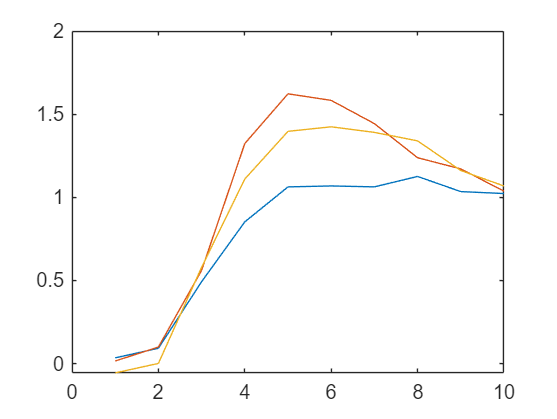

% Calculate palatability index of each neuron
nostim_palatability_idx_sigmod = palatability_idx(combined_trial_means_nostim);
stim_palatability_idx_sigmod = palatability_idx(combined_trial_means_stim);
stim_swap_palatability_idx_sigmod = palatability_idx(combined_trial_means_stim_swap);

plot(1:10, mean(nostim_palatability_idx_sigmod, 2))
hold on
plot(1:10, mean(stim_palatability_idx_sigmod, 2))
plot(1:10, mean(stim_swap_palatability_idx_sigmod, 2))
hold off


nostim_palatability_idx_tab = array2table(nostim_palatability_idx_sigmod);
stim_palatability_idx_tab = array2table(stim_palatability_idx_sigmod);
stim_palatability_idx_swap_tab = array2table(stim_swap_palatability_idx_sigmod);
% 
% filename = "Cohort 1+3 early palatability idx (5s BL).xlsx";
% writetable(nostim_palatability_idx_tab, filename, "Sheet", "No stim");
% writetable(stim_palatability_idx_tab, filename, "Sheet", "Stim");
% writetable(stim_palatability_idx_swap_tab, filename, "Sheet", "Swap");


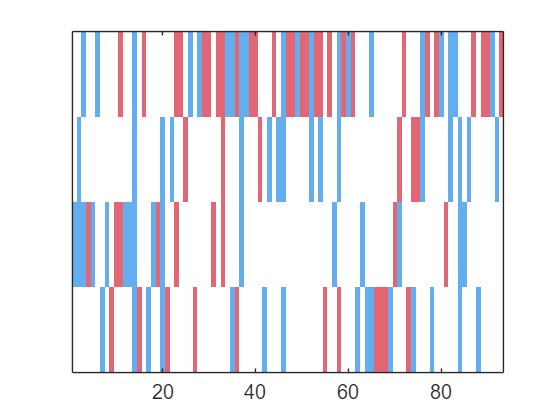

% Describe the direction of modulation
mod_direction = zeros(length(cell_list_for_analysis), 4);    % Increase or decrease in dF
mod_direction_abs = zeros(length(cell_list_for_analysis), 4); % Increase or decrease in response magnitude, regardless of direction

for cell = 1:length(cell_list_for_analysis)
    for taste = 1:4
        delta_response = sum(squeeze(combined_trial_means_stim(cell, :, taste)) ... 
                       - squeeze(combined_trial_means_nostim(cell, :, taste)));
        if delta_response > 1
            mod_direction(cell, taste) = 1;
        else
            mod_direction(cell, taste) = -1;
        end
        
        delta_response_abs = sum(abs(squeeze(combined_trial_means_stim(cell, :, taste))) ... 
                       - squeeze(abs(combined_trial_means_nostim(cell, :, taste))));
        if delta_response_abs > 1
            mod_direction_abs(cell, taste) = 1;
        else
            mod_direction_abs(cell, taste) = -1;
        end        

    end
end

mod_direction = mod_direction' .* sig_bool_DR;
mod_direction_abs = mod_direction_abs' .* sig_bool_DR;

mod_direction_sorted_1 = sortrows(mod_direction', [1 2 3 4], "descend")';
% mod_direction_abs_sorted = sortrows(mod_direction_abs', [1 2 3 4], "descend")';
% cmap = [0.224, 0.541, 0.918;
%         1 1 1;
%         0.878, 0.345, 0.541];
cmap = [0.3882, 0.6824, 0.9373;
        1 1 1;
        0.8863, 0.4, 0.4549];

imagesc(mod_direction); colormap(cmap);
set(gca, "YTick", [], "LineWidth", 1)

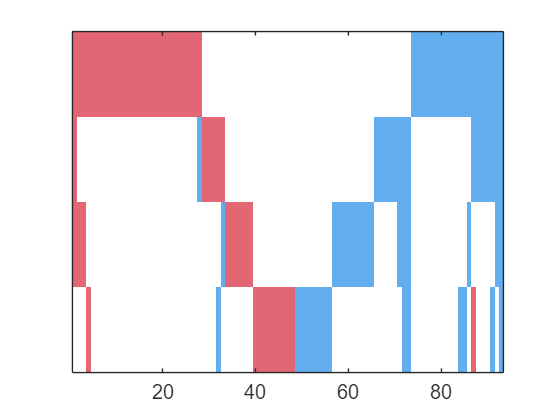

imagesc(mod_direction_sorted_1); colormap(cmap);
set(gca, "YTick", [],  "LineWidth", 1)


%imagesc(mod_direction_sorted_2)
%imagesc(mod_direction_abs_sorted)

% Decode taste stimuli using binned response of each cell
[accuracy_nostim, FP_same_nostim, FP_oppsite_nostim] = decode_neuron(combined_binned_sig_nostim);
[accuracy_stim, FP_same_stim, FP_oppsite_stim] = decode_neuron(combined_binned_sig_stim);

% FP_oppsite_nostim is divided by 2 to normalize probability.
nostim_neuron_decoding = [accuracy_nostim, FP_same_nostim, FP_oppsite_nostim/2];
nostim_neuron_decoding_tab = array2table(nostim_neuron_decoding);  % Change this line to get taste responsive/sigmod
stim_neuron_decoding = [accuracy_stim, FP_same_stim, FP_oppsite_stim/2];
stim_neuron_decoding_tab = array2table(stim_neuron_decoding);

filename = "Early stim single cell decoding (cohort 1 + 3).xlsx";
writetable(nostim_neuron_decoding_tab, filename, "Sheet", "No stim");
writetable(stim_neuron_decoding_tab, filename, "Sheet", "Stim");

accuracy_nostim(89)
accuracy_stim(89)

accuracy_diff = accuracy_nostim - accuracy_stim

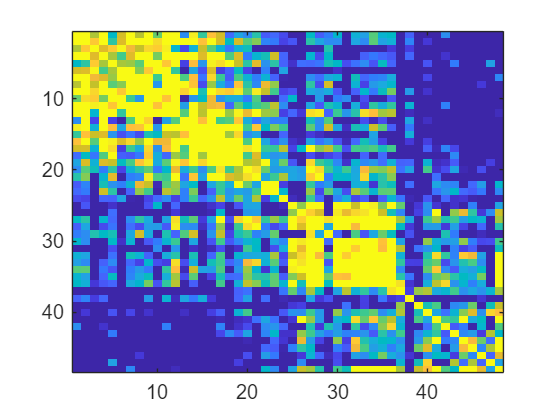

% Prepared data matrix for correlation analysis
clf
colormap("default")
combined_nostim_reshape = reshape(permute(combined_binned_sig_nostim, [2,1,3]), 48, []);
nostim_corr = corrcoef(combined_nostim_reshape');
imagesc(nostim_corr, [0.2, 0.5])

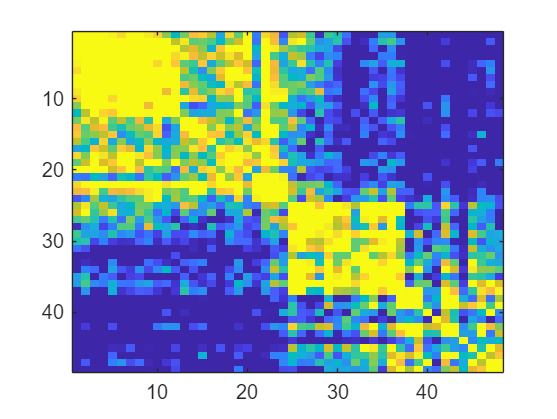


combined_stim_reshape = reshape(permute(combined_binned_sig_stim, [2,1,3]), 48, []);
stim_corr = corrcoef(combined_stim_reshape');
imagesc(stim_corr, [0.2, 0.5])

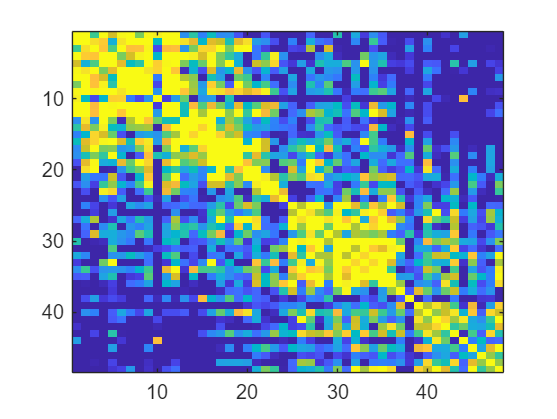

% Normalized the binned response of each cell by the absolute value of the
%  maximum trial mean response
S_binned_mean_nostim = mean(S_aligned_binned(:, nostim_trials,:), 2);
N_binned_mean_nostim = mean(N_aligned_binned(:, nostim_trials,:), 2);
C_binned_mean_nostim = mean(C_aligned_binned(:, nostim_trials,:), 2);
Q_binned_mean_nostim = mean(Q_aligned_binned(:, nostim_trials,:), 2);

S_binned_mean_stim = mean(S_aligned_binned(:, stim_trials,:), 2);
N_binned_mean_stim = mean(N_aligned_binned(:, stim_trials,:), 2);
C_binned_mean_stim = mean(C_aligned_binned(:, stim_trials,:), 2);
Q_binned_mean_stim = mean(Q_aligned_binned(:, stim_trials,:), 2);
combined_binned = cat(2,S_binned_mean_nostim, N_binned_mean_nostim, C_binned_mean_nostim, Q_binned_mean_nostim, ...
    S_binned_mean_stim, N_binned_mean_stim, C_binned_mean_stim, Q_binned_mean_stim);
combined_binned_abs = abs(combined_binned);
max_val = max(combined_binned_abs, [], [2,3]);  % Normalization factor

S_binned_norm = S_aligned_binned./max_val;
N_binned_norm = N_aligned_binned./max_val;
C_binned_norm = C_aligned_binned./max_val;
Q_binned_norm = Q_aligned_binned./max_val;

S_binned_norm_nostim = S_binned_norm(cell_list_for_analysis, nostim_trials, :);
N_binned_norm_nostim = N_binned_norm(cell_list_for_analysis, nostim_trials, :);
C_binned_norm_nostim = C_binned_norm(cell_list_for_analysis, nostim_trials, :);
Q_binned_norm_nostim = Q_binned_norm(cell_list_for_analysis, nostim_trials, :);

S_binned_norm_stim = S_binned_norm(cell_list_for_analysis, stim_trials, :);
N_binned_norm_stim = N_binned_norm(cell_list_for_analysis, stim_trials, :);
C_binned_norm_stim = C_binned_norm(cell_list_for_analysis, stim_trials, :);
Q_binned_norm_stim = Q_binned_norm(cell_list_for_analysis, stim_trials, :);

clf

% No stim correlation matrix
combined_bined_nostim_norm = cat(2, S_binned_norm_nostim, ...
                                  N_binned_norm_nostim, ...
                                  C_binned_norm_nostim, ...
                                  Q_binned_norm_nostim);
combined_nostim_norm_reshape = reshape(permute(combined_bined_nostim_norm, [2,1,3]), 48, []);
nostim_norm_corr = corrcoef(combined_nostim_norm_reshape');
imagesc(nostim_norm_corr, [0.1, 0.4])

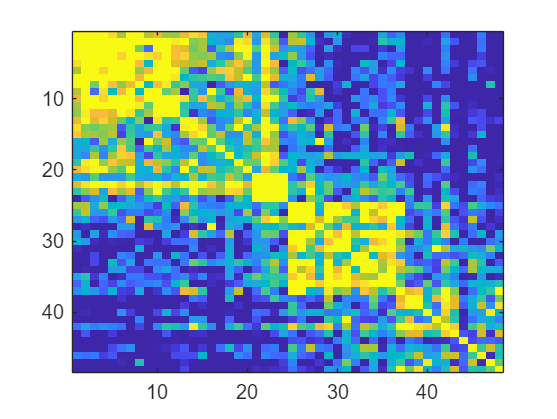


% Stim correlation matrix
combined_bined_stim_norm = cat(2, S_binned_norm_stim, ...
                                  N_binned_norm_stim, ...
                                  C_binned_norm_stim, ...
                                  Q_binned_norm_stim);
combined_stim_norm_reshape = reshape(permute(combined_bined_stim_norm, [2,1,3]), 48, []);
stim_norm_corr = corrcoef(combined_stim_norm_reshape');
imagesc(stim_norm_corr, [0.1, 0.4])

diff = stim_norm_corr - nostim_norm_corr;
imagesc(diff, [-0.2, 0.2])

% Prepare design matrix for PCA analysis

window = 41:100;
%timepoint_per_trial_type = length(window)*12;

S_nostim = S_aligned_df(cell_list_for_analysis, nostim_trials, window);
N_nostim = N_aligned_df(cell_list_for_analysis, nostim_trials, window);
C_nostim = C_aligned_df(cell_list_for_analysis, nostim_trials, window);
Q_nostim = Q_aligned_df(cell_list_for_analysis, nostim_trials, window);

S_stim = S_aligned_df(cell_list_for_analysis, stim_trials, window);
N_stim = N_aligned_df(cell_list_for_analysis, stim_trials, window);
C_stim = C_aligned_df(cell_list_for_analysis, stim_trials, window);
Q_stim = Q_aligned_df(cell_list_for_analysis, stim_trials, window);

% trial means, transposed (bins x cells)
S_nostim_trial_mean = squeeze(mean(S_nostim, 2))';
N_nostim_trial_mean = squeeze(mean(N_nostim, 2))';
C_nostim_trial_mean = squeeze(mean(C_nostim, 2))';
Q_nostim_trial_mean = squeeze(mean(Q_nostim, 2))';

S_stim_trial_mean = squeeze(mean(S_stim, 2))';
N_stim_trial_mean = squeeze(mean(N_stim, 2))';
C_stim_trial_mean = squeeze(mean(C_stim, 2))';
Q_stim_trial_mean = squeeze(mean(Q_stim, 2))';

trial_mean_design_mat = cat(1, S_nostim_trial_mean, ...
                                N_nostim_trial_mean, ...
                                C_nostim_trial_mean, ...
                                Q_nostim_trial_mean, ...
                                S_stim_trial_mean, ...
                                N_stim_trial_mean, ...
                                C_stim_trial_mean, ...
                                Q_stim_trial_mean);

trial_mean_design_mat_norm = trial_mean_design_mat ./ max_val(cell_list_for_analysis)';

% Use this block if performing PCA all trials instead of the trial means.

% cell_count = size(S_nostim, 1);
% total_timepoints = size(S_nostim, 2) * size(S_nostim, 3);
% S_nostim_reshaped = reshape(S_nostim, cell_count, total_timepoints)';
% N_nostim_reshaped = reshape(N_nostim, cell_count, total_timepoints)';
% C_nostim_reshaped = reshape(C_nostim, cell_count, total_timepoints)';
% Q_nostim_reshaped = reshape(Q_nostim, cell_count, total_timepoints)';
% 
% S_stim_reshaped = reshape(S_stim, cell_count, total_timepoints)';
% N_stim_reshaped = reshape(N_stim, cell_count, total_timepoints)';
% C_stim_reshaped = reshape(C_stim, cell_count, total_timepoints)';
% Q_stim_reshaped = reshape(Q_stim, cell_count, total_timepoints)';
% 
% all_trials_design_mat = cat(1, S_nostim_reshaped, ...
%     N_nostim_reshaped, ...
%     C_nostim_reshaped, ...
%     Q_nostim_reshaped, ...
%     S_stim_reshaped, ...
%     N_stim_reshaped, ...
%     C_stim_reshaped, ...
%     Q_stim_reshaped);
% all_trials_design_mat_norm = all_trials_design_mat ./ max_val(cell_list_for_analysis)';

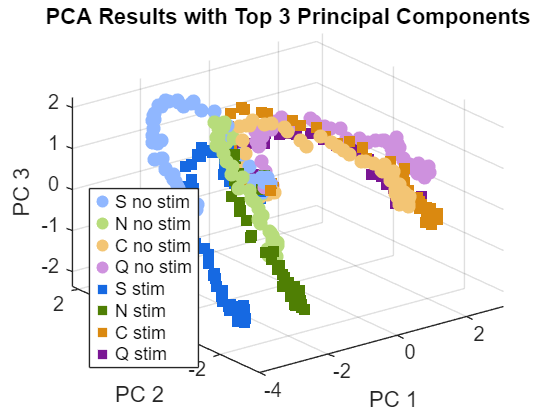


clf
% Perform PCA
[coeff, score, ~, ~, explained] = pca(trial_mean_design_mat_norm);

% Define colors for each class
% colors = [
%     0.68, 0.85, 0.90; % Light blue
%     0.56, 0.93, 0.56; % Light green
%     0.82, 0.71, 0.55; % Light brown
%     0.80, 0.60, 0.79; % Light purple
%     0, 0, 0.55;       % Dark blue
%     0, 0.39, 0;       % Dark green
%     0.55, 0.27, 0.07; % Dark brown
%     0.48, 0.06, 0.89  % Dark purple
% ];

colors = [
    "#90b7ff"; % Light blue
    "#b7dc7b"; % Light green
    "#f3c574"; % Light brown
    "#ce91de"; % Light purple
    "#1669e2";       % Dark blue
    "#4f7f04";       % Dark green
    "#da8910"; % Dark brown
    "#7a1694"  % Dark purple
];

shapes = ["o", "o", "o", "o", "square", "square", "square", "square"];

timepoint_per_trial_type = length(window);

% Plot the top 3 principal components
figure;
hold on;
for i = 1:8
    % Select data for the i-th class (251 observations per class)
    class_data = score((i-1)*timepoint_per_trial_type+1:i*timepoint_per_trial_type, 1:3);
    %class_data = score((i-1)*50+1:i*50, 1:3);
    % % Plot the data points for the i-th class with specified color
    scatter3(class_data(:, 1), class_data(:, 2), class_data(:, 3), 50, ...
             'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'none', ...
             'DisplayName', sprintf('Class %d', i), "Marker", shapes(i));
    % 
    % Plot the line connecting points in the i-th class
    % plot3(class_data(:, 1), class_data(:, 2), class_data(:, 3), ...
    %     'Color', colors(i, :), 'LineWidth', 1.5, ...
    %     'DisplayName', sprintf('Class %d', i));
end

% Label the axes
xlabel('PC 1');
ylabel('PC 2');
zlabel('PC 3');

% Add legend and title
legend({'S no stim', 'N no stim', 'C no stim', 'Q no stim', ...
        'S stim', 'N stim', 'C stim', 'Q stim'}, 'Location', 'best');
title('PCA Results with Top 3 Principal Components');
grid on;
hold off;

view(3);

% For each trial, average the response during a given window that's
% palatability-relevant
average_window = 65:85; % 1.5s to 3.5 s
% Average response during 1-4 sec post stimulus cell x trials
S_bin_mean = squeeze(mean(S_aligned_df(:,:, average_window), 3));
N_bin_mean = squeeze(mean(N_aligned_df(:,:, average_window), 3));
C_bin_mean = squeeze(mean(C_aligned_df(:,:, average_window), 3));
Q_bin_mean = squeeze(mean(Q_aligned_df(:,:, average_window), 3));

% Max val normalization
S_bin_mean = S_bin_mean ./ max_val;
N_bin_mean = N_bin_mean ./ max_val;
C_bin_mean = C_bin_mean ./ max_val;
Q_bin_mean = Q_bin_mean ./ max_val;

S_bin_mean_nostim = S_bin_mean(cell_list_for_analysis, nostim_trials, :);
N_bin_mean_nostim = N_bin_mean(cell_list_for_analysis, nostim_trials, :);
C_bin_mean_nostim = C_bin_mean(cell_list_for_analysis, nostim_trials, :);
Q_bin_mean_nostim = Q_bin_mean(cell_list_for_analysis, nostim_trials, :);

S_bin_mean_stim = S_bin_mean(cell_list_for_analysis, stim_trials, :);
N_bin_mean_stim = N_bin_mean(cell_list_for_analysis, stim_trials, :);
C_bin_mean_stim = C_bin_mean(cell_list_for_analysis, stim_trials, :);
Q_bin_mean_stim = Q_bin_mean(cell_list_for_analysis, stim_trials, :);


bin_mean_design_mat = cat(1,S_bin_mean_nostim', ...
    N_bin_mean_nostim', ...
    C_bin_mean_nostim', ...
    Q_bin_mean_nostim', ...
    S_bin_mean_stim', ...
    N_bin_mean_stim', ...
    C_bin_mean_stim', ...
    Q_bin_mean_stim');

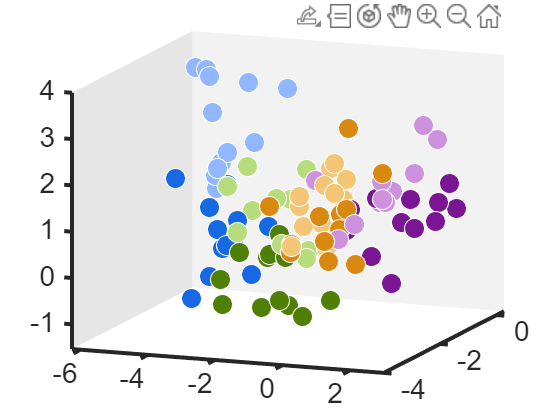

% Projecting trial-preserved data onto PCs defined using time-preserved data.
bin_mean_mat_projected = bin_mean_design_mat * coeff(:, 1:6);

trial_type_label = repelem(1:8, 12);

% Plot the top 3 principal components
clf
hold on;
for i = 1:8
    % Select data for the i-th class (251 observations per class)
    trial_type = (trial_type_label == i);
    class_data = bin_mean_mat_projected(trial_type, 1:3);
    
    %Plot the data points for the i-th class with specified color
    scatter3(class_data(:, 1), class_data(:, 2), class_data(:, 3), 100, ...
             'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'w', ...
             'DisplayName', sprintf('Class %d', i));
end

% Label the axes
% xlabel('PC 1');
% ylabel('PC 2');
% zlabel('PC 3');

% set(gca, "XTickLabel", []);
% set(gca, "YTickLabel", []);
% set(gca, "ZTickLabel", []);

grid off;
box off;
axis padded manual;
set(gca, "FontSize", 14, "FontName", "Arial", "LineWidth", 2, "GridLineWidth", 0.8);
view([21.1, 14.47]);


xlims = xlim;
ylims = ylim;
zlims = zlim;
add3DBoxShading(xlims, ylims, zlims);

% % Add legend and title
% legend({'S no stim', 'N no stim', 'C no stim', 'Q no stim', ...
%         'S stim', 'N stim', 'C stim', 'Q stim'}, 'Location', 'best');
% %title('PCA Results with Top 3 Principal Components');

hold off;
print(gcf, "pca", "-dpng", "-r1200");

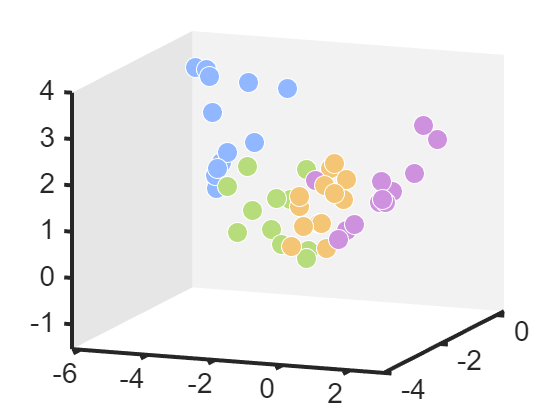

% Plot only the no stim trials for talk
clf
hold on;
for i = 1:4
    % Select data for the i-th class (251 observations per class)
    trial_type = (trial_type_label == i);
    class_data = bin_mean_mat_projected(trial_type, 1:3);
    
    %Plot the data points for the i-th class with specified color
    scatter3(class_data(:, 1), class_data(:, 2), class_data(:, 3), 100, ...
             'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'w', ...
             'DisplayName', sprintf('Class %d', i));
end

% Label the axes
% xlabel('PC 1');
% ylabel('PC 2');
% zlabel('PC 3');

% set(gca, "XTickLabel", []);
% set(gca, "YTickLabel", []);
% set(gca, "ZTickLabel", []);

grid off;
box off;
axis padded manual;
set(gca, "FontSize", 14, "FontName", "Arial", "LineWidth", 2, "GridLineWidth", 0.8);
view([21.1, 14.47]);
xlim(xlims);
ylim(ylims);
zlim(zlims);
add3DBoxShading(xlims, ylims, zlims);

hold off;

print(gcf, "pca nostim", "-dpng", "-r1200");

% Find the mean point of palatable tastes (no stim)
S_and_N_labels = trial_type_label == 1 | trial_type_label == 2;
palatable_mean_point = mean(bin_mean_mat_projected(S_and_N_labels, :), 1);

% Find the mean point of unpalatable tastes (no stim)
C_and_Q_labels = trial_type_label == 3 | trial_type_label == 4;
unpalatable_mean_point = mean(bin_mean_mat_projected(C_and_Q_labels, :), 1);

% palatability axis goes through the palatable and unpalatable mean points
palatability_vector = palatable_mean_point - unpalatable_mean_point;
% Divide by norm to make it a unit vector
palatability_axis = palatability_vector/norm(palatability_vector);

palatability_axis_center = (palatable_mean_point + unpalatable_mean_point)/2;
center_projected = palatability_axis_center * palatability_axis';
scaling_factor = sqrt(sum((palatable_mean_point - palatability_axis_center).^2));
p_projected = palatable_mean_point * palatability_axis';
(p_projected - center_projected) / scaling_factor

ans = 1.0000

up_projected = unpalatable_mean_point * palatability_axis';
(up_projected - center_projected) / scaling_factor

ans = -1.0000


bin_mean_p_projected = (bin_mean_mat_projected - palatability_axis_center) * palatability_axis';
bin_mean_pscore = bin_mean_p_projected / scaling_factor;

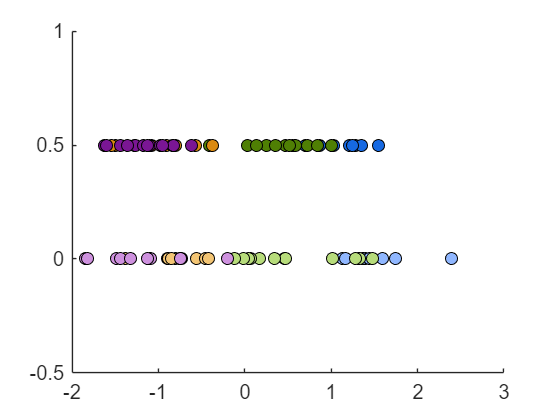

pscore_mat = zeros(12, 8); % 12 trials per trial type
clf
hold on

for i = 1:4
    trial_type = (trial_type_label == i);
    scatter(bin_mean_pscore(trial_type), zeros(1, 12), ...
        'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');

    pscore_mat(:, i) = bin_mean_pscore(trial_type);
end

for i = 5:8
    trial_type = (trial_type_label == i);
        scatter(bin_mean_pscore(trial_type), ones(1, 12) *0.5, ...
        'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
    
    pscore_mat(:, i) = bin_mean_pscore(trial_type);
end

ylim([-0.5, 1])

hold off

col_names = ["S nostim", "N nostim", "C nostim", "Q nostim",...
             "S stim", "N stim", "C stim", "Q stim"]

col_names = 1×8 string array
    "S nostim"    "N nostim"    "C nostim"    "Q nostim"    "S stim"    "N stim"    "C stim"    "Q stim"


pscore_tab = array2table(pscore_mat,"VariableNames", col_names);

filename = "Early stim PCA palatability score (cohort 1 + 3, 5s BL).xlsx";
writetable(pscore_tab, filename);

% Calculate the direction each taste shifted.
S_nostim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 1), :), 1);
N_nostim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 2), :), 1);
C_nostim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 3), :), 1);
Q_nostim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 4), :), 1);

S_stim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 5), :), 1);
N_stim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 6), :), 1);
C_stim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 7), :), 1);
Q_stim_mean_point = mean(bin_mean_mat_projected((trial_type_label == 8), :), 1);

S_shift_vector = S_stim_mean_point - S_nostim_mean_point;
N_shift_vector = N_stim_mean_point - N_nostim_mean_point;
C_shift_vector = C_stim_mean_point - C_nostim_mean_point;
Q_shift_vector = Q_stim_mean_point - Q_nostim_mean_point;

mean_shift_vector = (S_shift_vector + N_shift_vector + C_shift_vector + Q_shift_vector) / 4;

% Calculate the angle between the shift vector and palatability axis
dot_product = dot(mean_shift_vector, palatability_axis);
theta_shift_palatability = acos(dot_product / norm(mean_shift_vector) * norm(palatability_axis));
theta_shift_palatability_deg = 180 - rad2deg(theta_shift_palatability);


% Unused code.

% With max val normalization
% Calculate palatability index of each neuron
clf
nostim_palatability_idx_sigmod = palatability_idx(S_binned_norm_nostim, ...
    N_binned_norm_nostim, ...
    C_binned_norm_nostim, ...
    Q_binned_norm_nostim);
plot(1:10, mean(nostim_palatability_idx_sigmod, 2))
%ylim([-0.05, 0.3])
hold on
stim_palatability_idx_sigmod = palatability_idx(S_binned_norm_stim, ...
    N_binned_norm_stim, ...
    C_binned_norm_stim, ...
    Q_binned_norm_stim);
plot(1:10, mean(stim_palatability_idx_sigmod, 2))
%ylim([-0.05, 0.45])
hold off
% nostim_palatability_idx_tab = array2table(nostim_palatability_idx_sigmod);
% stim_palatability_idx_tab = array2table(stim_palatability_idx_sigmod);
% 
% filename = "Cohort 3 early palatability idx (sigmod norm with log).xlsx";
% writetable(nostim_palatability_idx_tab, filename, "Sheet", "No stim");
% writetable(stim_palatability_idx_tab, filename, "Sheet", "Stim");

S_nostim_ROC = ROC_PSTH(S_aligned(:, nostim_trials, :));
N_nostim_ROC = ROC_PSTH(N_aligned(:, nostim_trials, :));
C_nostim_ROC = ROC_PSTH(C_aligned(:, nostim_trials, :));
Q_nostim_ROC = ROC_PSTH(Q_aligned(:, nostim_trials, :));

S_stim_ROC = ROC_PSTH(S_aligned(:, stim_trials, :));
N_stim_ROC = ROC_PSTH(N_aligned(:, stim_trials, :));
C_stim_ROC = ROC_PSTH(C_aligned(:, stim_trials, :));
Q_stim_ROC = ROC_PSTH(Q_aligned(:, stim_trials, :));

nostim_palatability_idx_ROC = palatability_idx_ROC(S_nostim_ROC, ...
    N_nostim_ROC, ...
    C_nostim_ROC, ...
    Q_nostim_ROC, sig_mod_DR);

stim_palatability_idx_ROC = palatability_idx_ROC(S_stim_ROC, ...
    N_stim_ROC, ...
    C_stim_ROC, ...
    Q_stim_ROC, sig_mod_DR);

plot(1:10, mean(nostim_palatability_idx_ROC, 2))
hold on
plot(1:10, mean(stim_palatability_idx_ROC, 2))
hold off

[nostim_mat_sorted, stim_mat_sorted] = taste_profile_clustering(mean_response_nostim_normalized(:, taste_responsive), ...
                                                    mean_response_stim_normalized(:, taste_responsive));

 sorted_profiles_combined = [nostim_mat_sorted; stim_mat_sorted]';

% Define the number of clusters
k = 2;
rng("default");

% Perform k-means clustering
[idx, centroids] = kmeans(sorted_profiles_combined, k);

% Use PCA to reduce the data to 2 dimensions for visualization
[coeff, score] = pca(sorted_profiles_combined);

% Define colors for each cluster
colors = lines(k); % 'lines' colormap can be replaced with other colormaps

% Plot the data points with different colors for each cluster
figure;
hold on;
for i = 1:k
    scatter(score(idx == i, 1), score(idx == i, 2), 36, colors(i, :), 'filled');
end
hold off;


bar(centroids(2,:))

% Entropy calculation
[mean_response_nostim, mean_response_nostim_normalized, entropy_nostim] = get_entropy(S_aligned_df(:, nostim_trials, :), ...
    N_aligned_df(:, nostim_trials, :), ...
    C_aligned_df(:, nostim_trials, :), ...
    Q_aligned_df(:, nostim_trials, :), 0, 5);

[mean_response_stim,  mean_response_stim_normalized, entropy_stim] = get_entropy(S_aligned_df(:, stim_trials, :), ...
    N_aligned_df(:, stim_trials, :), ...
    C_aligned_df(:, stim_trials, :), ...
    Q_aligned_df(:, stim_trials, :), 0, 5);

[mean_response_nostim_normalized, entropy_nostim] = get_entropy_v2(combined_trial_means_nostim);
[mean_response_stim_normalized, entropy_stim] = get_entropy_v2(combined_trial_means_stim);
[mean_response_swap_normalized, entropy_swap] = get_entropy_v2(combined_trial_means_stim_swap);

entropy_combined = [entropy_nostim; entropy_stim; entropy_swap];
entropy_tab_sig = array2table(entropy_combined);
writetable(entropy_tab_sig, "Early stim entropy swap(Cohort 1+3).xlsx")

%Compare the entropy of significantly modulated cells with and with stim
entropy_nostim_selected = entropy_nostim(cell_list_for_analysis)

entropy_nostim_selected =     0.7053    1.0000    0.0000    0.9706    1.0000    0.9213    0.0000    0.6096    1.0000    0.9670    0.9982    0.2080    0.3738    0.7643    1.0000    0.1376    0.4989    0.7509    0.4224    0.4620    0.8644    0.7665    0.8853    0.9725    0.8603    0.7009    0.8008    0.0000    0.9512    0.8882    0.1905    0.2394    0.6938    0.4968    1.0000    0.8817    1.0000    0.6735    0.9341    0.3354    0.7880    1.0000    0.9466    0.4168    0.3174    0.6207    0.7897    0.9830    0.9398    0.0000


entropy_stim_selected =  entropy_stim(cell_list_for_analysis)

entropy_stim_selected =     0.4955    1.0000    1.0000    0.7730    1.0000    0.4180    1.0000    0.2554    0.0000    0.7155    0.5961    0.0000    1.0000    0.0000    1.0000    1.0000    0.0000    0.9592    0.4134    0.0000    0.1965    0.0000    0.6846    0.0000    0.8682    0.9104    0.5235    0.0000    0.0000    0.7334    0.7915    0.2338    0.9565    0.0000    0.2153    0.0000    0.0000    0.9848    0.9896    1.0000    0.4437    0.4988    0.8354    0.5473    0.9937    0.4940    0.3580    0.1909    0.9334    0.0000


entropy_combined = [entropy_nostim_selected; entropy_stim_selected]

entropy_combined =     0.7053    1.0000    0.0000    0.9706    1.0000    0.9213    0.0000    0.6096    1.0000    0.9670    0.9982    0.2080    0.3738    0.7643    1.0000    0.1376    0.4989    0.7509    0.4224    0.4620    0.8644    0.7665    0.8853    0.9725    0.8603    0.7009    0.8008    0.0000    0.9512    0.8882    0.1905    0.2394    0.6938    0.4968    1.0000    0.8817    1.0000    0.6735    0.9341    0.3354    0.7880    1.0000    0.9466    0.4168    0.3174    0.6207    0.7897    0.9830    0.9398    0.0000
    0.4955    1.0000    1.0000    0.7730    1.0000    0.4180    1.0000    0.2554    0.0000    0.7155    0.5961    0.0000    1.0000    0.0000    1.0000    1.0000    0.0000    0.9592    0.4134    0.0000    0.1965    0.0000    0.6846    0.0000    0.8682    0.9104    0.5235    0.0000    0.0000    0.7334    0.7915    0.2338    0.9565    0.0000    0.2153    0.0000    0.0000    0.9848    0.9896    1.0000    0.4437    0.4988    0.8354    0.5473    0.9937    0.4940    0.3580    0.1909

entropy_tab_sig = array2table(entropy_combined);
writetable(entropy_tab_sig, "Early stim entropy (Cohort 1+3).xlsx")

% %Compare the entropy of significantly modulated cells with and with stim (sig mod)
% entropy_nostim_selected = entropy_nostim(sig_mod)
% entropy_stim_selected =  entropy_stim(sig_mod)
% entropy_combined = [entropy_nostim_selected; entropy_stim_selected]
% entropy_tab_sig = array2table(entropy_combined);
% writetable(entropy_tab_sig, "Early stim CaMKII entropy (sig_mod).xlsx")

% How does stim affect the response magnitude for each taste?
taste_response_diff = mean_response_stim - mean_response_nostim;

delta_S = taste_response_diff(1, sig_S)

delta_N = taste_response_diff(2, sig_N)

delta_C = taste_response_diff(3, sig_C)

delta_Q = taste_response_diff(4, sig_Q)

max_length = max([length(delta_S), length(delta_N), length(delta_C), length(delta_Q)]);

delta_S_padded = [delta_S'; NaN(max_length - length(delta_S), 1)];
delta_N_padded = [delta_N'; NaN(max_length - length(delta_N), 1)];
delta_C_padded = [delta_C'; NaN(max_length - length(delta_C), 1)];
delta_Q_padded = [delta_Q'; NaN(max_length - length(delta_Q), 1)];
sig_mod
padded_tab = array2table([delta_S_padded, delta_N_padded, delta_C_padded, delta_Q_padded]);

 writetable(padded_tab, "Early stim mDlx delta taste responses.xlsx")

S_aligned_norm =S_aligned_df./max_val;
N_aligned_norm =N_aligned_df./max_val;
C_aligned_norm =C_aligned_df./max_val;
Q_aligned_norm =Q_aligned_df./max_val;

% Population decoding of taste indentity
S_binned_nostim = S_aligned_binned(taste_responsive, nostim_trials, :);
N_binned_nostim = N_aligned_binned(taste_responsive, nostim_trials, :);
C_binned_nostim = C_aligned_binned(taste_responsive, nostim_trials, :);
Q_binned_nostim = Q_aligned_binned(taste_responsive, nostim_trials, :);

combined_binned_nostim = cat(2,S_binned_nostim, N_binned_nostim, C_binned_nostim, Q_binned_nostim);

S_binned_stim = S_aligned_binned(taste_responsive, stim_trials, :);
N_binned_stim = N_aligned_binned(taste_responsive, stim_trials, :);
C_binned_stim = C_aligned_binned(taste_responsive, stim_trials, :);
Q_binned_stim = Q_aligned_binned(taste_responsive, stim_trials, :);

combined_binned_stim = cat(2,S_binned_stim, N_binned_stim, C_binned_stim, Q_binned_stim);

% 10-fold cross validation with no repeats
no_stim_decode_accuracy = decode_bin_NR(combined_binned_nostim, 6);
stim_decode_accuracy = decode_bin_NR(combined_binned_stim, 6);

mean(no_stim_decode_accuracy, 2)
mean(stim_decode_accuracy, 2)

S_binned_nostim = S_aligned_binned(taste_responsive, nostim_trials, :);
N_binned_nostim = N_aligned_binned(taste_responsive, nostim_trials, :);
C_binned_nostim = C_aligned_binned(taste_responsive, nostim_trials, :);
Q_binned_nostim = Q_aligned_binned(taste_responsive, nostim_trials, :);

combined_binned_nostim = cat(2,S_binned_nostim, N_binned_nostim, C_binned_nostim, Q_binned_nostim);

S_binned_stim = S_aligned_binned(taste_responsive, stim_trials, :);
N_binned_stim = N_aligned_binned(taste_responsive, stim_trials, :);
C_binned_stim = C_aligned_binned(taste_responsive, stim_trials, :);
Q_binned_stim = Q_aligned_binned(taste_responsive, stim_trials, :);

combined_binned_stim = cat(2,S_binned_stim, N_binned_stim, C_binned_stim, Q_binned_stim);

% S_binned_nostim = S_aligned_binned(sig_mod, nostim_trials, :);
% N_binned_nostim = N_aligned_binned(sig_mod, nostim_trials, :);
% C_binned_nostim = C_aligned_binned(sig_mod, nostim_trials, :);
% Q_binned_nostim = Q_aligned_binned(sig_mod, nostim_trials, :);
% 
% combined_binned_nostim = cat(2,S_binned_nostim, N_binned_nostim, C_binned_nostim, Q_binned_nostim);
% 
% S_binned_stim = S_aligned_binned(sig_mod, stim_trials, :);
% N_binned_stim = N_aligned_binned(sig_mod, stim_trials, :);
% C_binned_stim = C_aligned_binned(sig_mod, stim_trials, :);
% Q_binned_stim = Q_aligned_binned(sig_mod, stim_trials, :);
% 
% combined_binned_stim = cat(2,S_binned_stim, N_binned_stim, C_binned_stim, Q_binned_stim);

S_binned_nostim = S_aligned_binned(:, nostim_trials, :);
N_binned_nostim = N_aligned_binned(:, nostim_trials, :);
C_binned_nostim = C_aligned_binned(:, nostim_trials, :);
Q_binned_nostim = Q_aligned_binned(:, nostim_trials, :);

combined_binned_nostim = cat(2,S_binned_nostim, N_binned_nostim, C_binned_nostim, Q_binned_nostim);

S_binned_stim = S_aligned_binned(:, stim_trials, :);
N_binned_stim = N_aligned_binned(:, stim_trials, :);
C_binned_stim = C_aligned_binned(:, stim_trials, :);
Q_binned_stim = Q_aligned_binned(:, stim_trials, :);

combined_binned_stim = cat(2,S_binned_stim, N_binned_stim, C_binned_stim, Q_binned_stim);

S_nostim_responsive_tab = array2table(find(S_nostim_responsive));
N_nostim_responsive_tab = array2table(find(N_nostim_responsive));
C_nostim_responsive_tab = array2table(find(C_nostim_responsive));
Q_nostim_responsive_tab = array2table(find(Q_nostim_responsive));

S_stim_responsive_tab = array2table(find(S_stim_responsive));
N_stim_responsive_tab = array2table(find(N_stim_responsive));
C_stim_responsive_tab = array2table(find(C_stim_responsive));
Q_stim_responsive_tab = array2table(find(Q_stim_responsive));

filename = "Tonic stim CaMKII responsive cells count.xlsx";
writetable(S_nostim_responsive_tab, filename, "Sheet", "S no stim");
writetable(N_nostim_responsive_tab, filename, "Sheet", "N no stim");
writetable(C_nostim_responsive_tab, filename, "Sheet", "C no stim");
writetable(Q_nostim_responsive_tab, filename, "Sheet", "Q no stim");
writetable(S_stim_responsive_tab, filename, "Sheet", "S stim");
writetable(N_stim_responsive_tab, filename, "Sheet", "N stim");
writetable(C_stim_responsive_tab, filename, "Sheet", "C stim");
writetable(Q_stim_responsive_tab, filename, "Sheet", "Q stim");

% Use this block for sig mod neurons
cell_list_for_analysis = sig_mod_DR;

S_binned_sig_nostim = S_aligned_binned(cell_list_for_analysis, nostim_trials, :);
N_binned_sig_nostim = N_aligned_binned(cell_list_for_analysis, nostim_trials, :);
C_binned_sig_nostim = C_aligned_binned(cell_list_for_analysis, nostim_trials, :);
Q_binned_sig_nostim = Q_aligned_binned(cell_list_for_analysis, nostim_trials, :);

combined_binned_sig_nostim = cat(2,S_binned_sig_nostim, N_binned_sig_nostim, C_binned_sig_nostim, Q_binned_sig_nostim);

S_binned_sig_stim = S_aligned_binned(cell_list_for_analysis, stim_trials, :);
N_binned_sig_stim = N_aligned_binned(cell_list_for_analysis, stim_trials, :);
C_binned_sig_stim = C_aligned_binned(cell_list_for_analysis, stim_trials, :);
Q_binned_sig_stim = Q_aligned_binned(cell_list_for_analysis, stim_trials, :);

combined_binned_sig_stim = cat(2,S_binned_sig_stim, N_binned_sig_stim, C_binned_sig_stim, Q_binned_sig_stim);

% 10-fold cross validation with no repeats
no_stim_decode_accuracy = decode_bin_NR(combined_binned_sig_nostim, 6);
stim_decode_accuracy = decode_bin_NR(combined_binned_sig_stim, 6);

mean(no_stim_decode_accuracy, 2)
mean(stim_decode_accuracy, 2)